# ESERCITAZIONE___20/02/2026___SALVATORE_RAIOLA_DE6000008

clear; close all; clc;

## 0)  DEFINIZIONI

#### Variabili simboliche 

syms x theta dx dtheta ddx ddtheta u real

#### Parametri

M = 0.8;
m = 0.2;
l = 0.3;
I = 0.006;
b = 0.08;
c = 0.002;
g = 0.81;

J = I + m*l^2;

#### I-S-U

% Stato
X = [x;
     dx;
     theta;
     dtheta];

% Uscita
Y = [x;
     theta];

% dimensioni
n = size(X,1);
m = 1;
v = size(Y,1);

#### Modello dinamico Non lineare

eq_1_sym = (M+m)*ddx + m*l*cos(theta)*ddtheta == u - b*dx + m*l*sin(theta)*theta^2;
eq_2_sym = m*l*cos(theta)*ddx + J*ddtheta == -c*theta + m*g*l*sin(theta);

eqs_sym =[eq_1_sym;
          eq_2_sym];

f_sym = solve(eqs_sym, [ddx, ddtheta], "ReturnConditions",true);

% dx/dt
f = [dx;
     f_sym.ddx;
     dtheta;
     f_sym.ddtheta];
% y
g = Y;

## 1)  PUNTI DI EQUILIBRIO E LINEARIZZAZIONE

#### Punti di equilibrio per u* = 0

eqs_peql = subs(eqs_sym, [dx; dtheta; ddx; ddtheta; u], [0; 0; 0; 0; 0]);
eq_theta = eqs_peql(1, :)

$$eq\_theta = 0=\frac{3\,\theta^{2}\,\sin\left(\theta \right)}{10}$$

peql = solve(eq_theta, theta, "ReturnConditions",true)

peql = struct with fields:
         theta: [3×1 sym]
    parameters: k
    conditions: [3×1 sym]


X_star = [peql.theta
          0]

$$X\_star = \left(\begin{array}{c} 0\\ 0\\ \pi \,k\\ 0 \end{array}\right)$$

#### Modello Linearizzato nell'intorno di X_star assumendo p = 0

A_sym = jacobian(f,X);
B_sym = jacobian(f,u);
C_sym = jacobian(g,X);
D_sym = jacobian(g,u);


A = double(subs(A_sym, [x; theta; u], [0; pi; 0]));
B = double(subs(B_sym, [x; theta; u], [0; pi; 0]));
C = double(subs(C_sym, [x; theta; u], [0; pi; 0]));
D = double(subs(D_sym, [x; theta; u], [0; pi; 0]));

sys = ss(A, B, C, D)


sys =
 
  A = 
            x1       x2       x3       x4
   x1        0        1        0        0
   x2        0  0.04103    3.089        0
   x3        0        0        0        1
   x4        0   0.5128     28.4        0
 
  B = 
            u1
   x1        0
   x2  -0.5128
   x3        0
   x4    -6.41
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
   y2   0   0   1   0
 
  D = 
       u1
   y1   0
   y2   0
 
Continuous-time state-space model.


#### Verifica Stabilità, osservabilità e controllabiilità

Stabilità

eig(A)

ans =          0
   -0.0147
   -5.3016
    5.3573


Controllabilità

if rank(ctrb(A,B)) == n
    disp('Il sistema è completamente raggiungibile');
else
    disp('Il sistema NON è completamente raggiungibile');
end

Il sistema è completamente raggiungibile


Osservabilità

if rank(obsv(A,C)) == n
    disp('Il sistema è completamente osservabile');
else
    disp('Il sistema NON è completamente osservabile');
end

Il sistema è completamente osservabile


## 2)  ASSEGNAMENTO AUTOVALORI

#### Specifiche

% Condizione iniziale
X0 = [0.1;
      0;
      deg2rad(12);
      0];

% Autovalori desiderati
eig_des = [-2, -2.5, -3, -3.5];

#### Sintesi

K_eig = place(A, B, eig_des);
A_cl_eig = A - B*K_eig;
eig(A_cl_eig)

ans =    -3.5000
   -3.0000
   -2.5000
   -2.0000


#### Verifica Simulazione

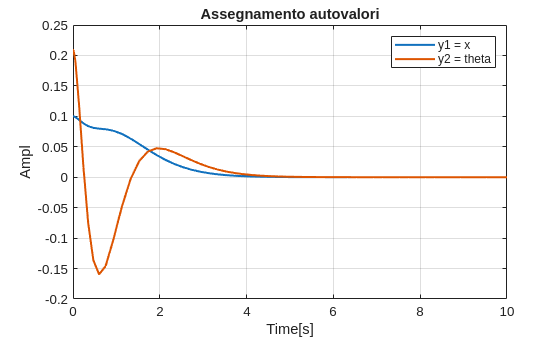

% Plot MATLAB
out = sim('EIG.slx');
y1 = out.y1.Data;
y2 = out.y2.Data;
time = out.y1.Time;

figure
plot(time, y1, "LineWidth", 1.5);
grid on
hold on
plot(time, y2, "LineWidth", 1.5);
xlabel("Time[s]");
ylabel("Ampl");
legend('y1 = x', 'y2 = theta');
title('Assegnamento autovalori');

## 3)  APPROCCIO ALLA LYAPUNOV

#### Specifiche

x_ref = 0.2;

#### Sintesi

cvx_clear
cvx_begin sdp quiet
cvx_precision high

    variable Q(n,n) symmetric
    variable L(m,n)

    minimize(0);

    subject to:
        Q >= (1e-6)*eye(n);   % Q semidefinita positiva
        A*Q + Q*A' + B*L + L'*B' <= (1e-6)*eye(n); 
cvx_end

K_LMI = -L/Q

K_LMI =    -0.2850   -0.7440   -5.2287   -0.3479



A_cl_lmi = A -B*K_LMI;
eig(A_cl_lmi)

ans =   -0.8905 + 1.6200i
  -0.8905 - 1.6200i
  -0.3948 + 0.5298i
  -0.3948 - 0.5298i


#### Compensazione del guadagno

sys_cl_lmi = ss(A_cl_lmi, B, C(1, :), D(1,:));

gain_lmi = dcgain(sys_cl_lmi);

N = pinv(gain_lmi)

N = -0.2850

#### Verifica Simulazione

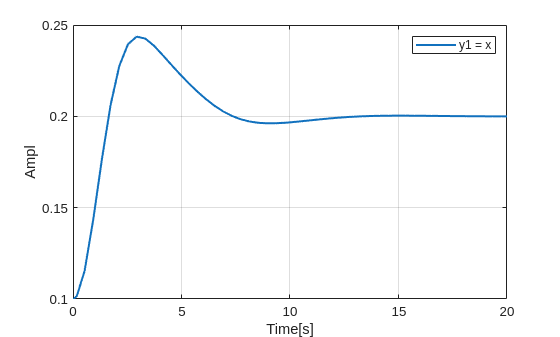

% Plot MATLAB
out = sim('LMI.slx');
y1 = out.y1.Data;
ref = out.ref.Data;
time = out.y1.Time;

figure
plot(time, y1, "LineWidth", 1.5);
grid on
xlabel("Time[s]");
ylabel("Ampl");
legend('y1 = x');

## 4)  CONTROLLO LQR CON AZIONE INTEGRALE

#### Specifiche 

% Tempo di Assestamento
Ts = 5;
alpha = 4/Ts;

#### Sistema aumentato con errore su x

C_LQR = C(1,:);

A_aug = [A, zeros(n,1);
         -C_LQR, 0];

n_aug = size(A_aug,1);

% Shift di A_aug per rispettare la specifica sul Ts
A_hat = A_aug + alpha*eye(n_aug);

B_aug = [B;
         0];

C_aug = [eye(n), zeros(n,1)];

D_aug = zeros(n,1);

sys_aug = ss(A_hat, B_aug, C_aug, D_aug)


sys_aug =
 
  A = 
           x1      x2      x3      x4      x5
   x1     0.8       1       0       0       0
   x2       0   0.841   3.089       0       0
   x3       0       0     0.8       1       0
   x4       0  0.5128    28.4     0.8       0
   x5      -1       0       0       0     0.8
 
  B = 
            u1
   x1        0
   x2  -0.5128
   x3        0
   x4    -6.41
   x5        0
 
  C = 
       x1  x2  x3  x4  x5
   y1   1   0   0   0   0
   y2   0   1   0   0   0
   y3   0   0   1   0   0
   y4   0   0   0   1   0
 
  D = 
       u1
   y1   0
   y2   0
   y3   0
   y4   0
 
Continuous-time state-space model.


#### Sintesi LQR

Q_bar = 1;
Q = C_aug'*Q_bar*C_aug + blkdiag(zeros(n,n), 20)

Q =      1     0     0     0     0
     0     1     0     0     0
     0     0     1     0     0
     0     0     0     1     0
     0     0     0     0    20


R = eye(m)

R = 1

K_LQR = lqr(sys_aug, Q, R)

K_LQR =   -79.9173  -58.8173  -16.6932    1.7060   39.7213


K_LQR_x = K_LQR(:, 1:n);
K_LQR_i = K_LQR(:, n+1:end);

#### Verifica Simulazione

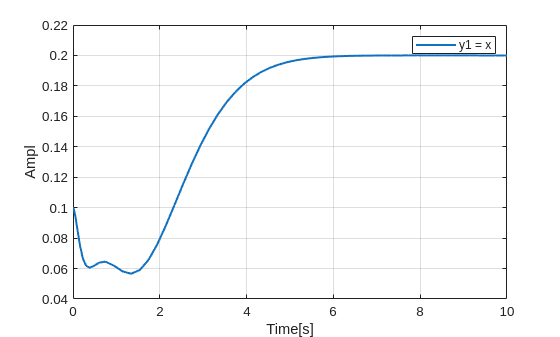

% Plot MATLAB
out = sim('LQR.slx');
y1 = out.y1.Data;
time = out.y1.Time;

figure
plot(time, y1, "LineWidth", 1.5);
grid on
xlabel("Time[s]");
ylabel("Ampl");
legend('y1 = x');

## 5)  CONTROLLO LQG con azione integrale

#### Specifiche

Qv = (10^-4)*eye(n);
Rv = (10^-3)*eye(v);

#### Sintesi

% Supponiamo che il rumore sia su tutti gli stati
G = eye(n);

sys_kf = ss(A, [B, G], C, [D, zeros(2,4)])


sys_kf =
 
  A = 
            x1       x2       x3       x4
   x1        0        1        0        0
   x2        0  0.04103    3.089        0
   x3        0        0        0        1
   x4        0   0.5128     28.4        0
 
  B = 
            u1       u2       u3       u4       u5
   x1        0        1        0        0        0
   x2  -0.5128        0        1        0        0
   x3        0        0        0        1        0
   x4    -6.41        0        0        0        1
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
   y2   0   0   1   0
 
  D = 
       u1  u2  u3  u4  u5
   y1   0   0   0   0   0
   y2   0   0   0   0   0
 
Continuous-time state-space model.



[~, L, P] = kalman(sys_kf, Qv, Rv);

disp('Guadagni del filtro di Kalman (L):'); disp(L);

Guadagni del filtro di Kalman (L):
    0.9375    0.9915
    0.8810    6.1182
    0.9915   10.6260
    5.3466   56.8970



A_kf = A - L*C;
eig(A_kf)

ans =   -0.4294 + 0.3657i
  -0.4294 - 0.3657i
  -5.4905 + 0.0000i
  -5.1731 + 0.0000i


B_kf = [B L];
C_kf = eye(n);
D_kf = zeros(n, size(B_kf,2));
KalmanFilter = ss(A_kf, B_kf, C_kf, D_kf)


KalmanFilter =
 
  A = 
            x1       x2       x3       x4
   x1  -0.9375        1  -0.9915        0
   x2   -0.881  0.04103   -3.029        0
   x3  -0.9915        0   -10.63        1
   x4   -5.347   0.5128   -28.49        0
 
  B = 
            u1       u2       u3
   x1        0   0.9375   0.9915
   x2  -0.5128    0.881    6.118
   x3        0   0.9915    10.63
   x4    -6.41    5.347     56.9
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
   y2   0   1   0   0
   y3   0   0   1   0
   y4   0   0   0   1
 
  D = 
       u1  u2  u3
   y1   0   0   0
   y2   0   0   0
   y3   0   0   0
   y4   0   0   0
 
Continuous-time state-space model.


#### Verifica Simulazione

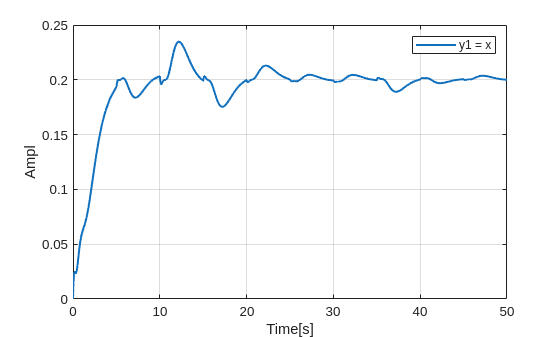

% Plot MATLAB
out = sim('LQG.slx');
y1 = out.y1.Data;
time = out.y1.Time;

figure
plot(time, y1, "LineWidth", 1.5);
grid on
xlabel("Time[s]");
ylabel("Ampl");
legend('y1 = x');